Denne øvelse fokuserer på anvendelse af Short Time Fourier-Transform (STFT). Denne opdeler et længere signal, hvis frekvensforløb ændrer sig, i små dele, der kan analyseres for dig. Der ønskes altså at afbilde frekvensspektret som funktion af tiden. Den mest simple måde at gøre dette er med et såkaldt spectrogram (X(f,t)-plot).

**Tids-/frekvensanalyse, spectrogram (DFT-baseret):**

Signalet opdeles i blokke på længden N samples, eventuelt overlappende. Hver blok udvælges med en vinduesfunktion w(n) af længde N. N-punkts DFT'en af dette vægtede signaludsnit beregnes. Denne udregning giver således frekvensspektret af signalet til tiden n.

Spectrogrammet kan ikke afbildes i en to-dimensionel figur, og der anvendes derfor et konturplot, hvor farven indikerer frekvensernes amplitude.

MATLAB har indbygget funktion til beregning og plotning af spektrogrammer.

En matrix beregnes med tiden n som søjleindex og frekvensen k som rækkeindex.

**Eksempler på spectrogrammer:**

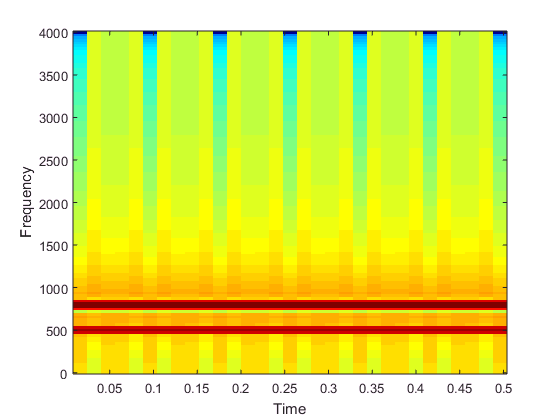

N = 4096;
n = 0:N-1;
f1 = 500;
f2 = 800;
fs = 8000;
Ts = 1/fs;
x2 = sin(2*pi*n*f1*Ts) + 2*sin(2*pi*n*f2*Ts);
specgram(x2,256,fs,hamming(256),128); colormap(jet) % Der kan ligeledes anvendes 1-gray eller gray colormap, se help colormap og help graph3d.

**Tidsopløsning og frekvensopløsning i spectrogrammer (usikkerhedsrelation):**

Ved N-punkts DFT af en blok med N samples, bliver opløsningen i tid og frekvens principielt:

Delta-t = N * Ts og Delta-f = fs / N

Tidsopløsningen og frekvensopløsningen kan altså ikke smatidig gøres vilkårlig god (lille), idet en god tidsopløsning afhænger af lille bloklængde og omvendt for frekvensopløsning. Dette kaldes usikkerhedsrelationen for spektralanalyse.

Ved anvendelse af vinduer resulterer, dette i en yderligere nedsat frekvensopløsning svarende til vinduets main-lobe-bredde. Ved f.eks. et Hamming-vindue fås:

delta-t = 1/2 * N * Ts og delta-f = 2 * fs / N.

Studer dette med følgende eksempel på en frekvens, der er til stede i hele signalets længde og en anden, der kun er tilstede midterst i signalet:

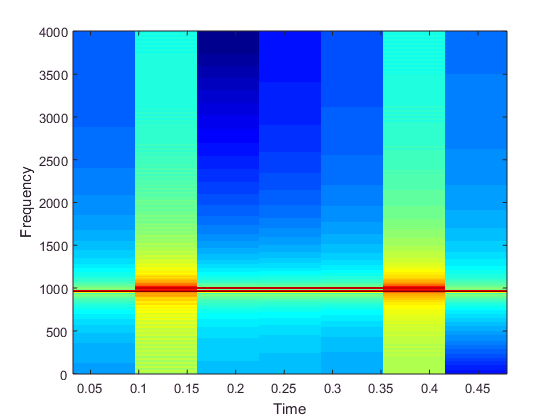

f1 = 960;
f2 = 1000;
n1 = 0:N-1;
n2 = 0:(N/2-1);
x2a = sin(2*pi*n1*f1*Ts);
x2b = [zeros(1,N/4) sin(2*pi*n2*f2*Ts) zeros(1,N/4)];
x2 = x2a + x2b;
specgram(x2,1024,fs,hamming(1024),512); colormap(jet)

Ved at ændre på værdierne i specgram bemærkes det, at en højere N giver bedre frekvensopløsning men værre tidsopløsning.